# PRÁCTICA 1 - DETECCIÓN AUTOMÁTICA DE EQUIPOS DE FUTBOL EN IMÁGENES

#### Tips y cosas:

- 30% de la Nota de Laboratorio

- Hay que probar RGB y HSV a ver que es mejor

- Mirar bien los bins de los histogramas para hacer la comparación

- Normalizar para hacer el problema más tratable

- Normalizar HSV => Eliminar V

- Tantos histogramas para el modelo como hagan falta: 2 o 3 => Para variar las posibilidades de histograma: Mucho blaugrana, poco blaugrana, etc

- Probar a hacer recortes aleatorios, toda la imagen, etc...

- Para la comparación la distribución de color tiene que ser significativamente igual.

- Se puede utilizar automaización de detección de formas de camiseta.

- Comparación de histogramas (de vecindad): Mínimos Cuadrados (post filtrado gaussiano), Chi-Square.

- Histograma 3-dimensional (con tripletas, no histograma 3D)

- Reducir los colores: Cada 4, 8 16 niveles de rojo, azul, verde => Para que coincidan los histogramas.

- Se puede aplicar normalización de color => Obtenemos una aplicación más tolerante a cambios de color y nos podemos cargar una componente => Histograma bidimensional.

syms R G B
r = R/(R+G+B)

$$r = \frac{R}{B+G+R}$$

g = G/(R+G+B)

$$g = \frac{G}{B+G+R}$$

b = B/(R+G+B)

$$b = \frac{B}{B+G+R}$$

## Global Dsefinitions

### Barça Model

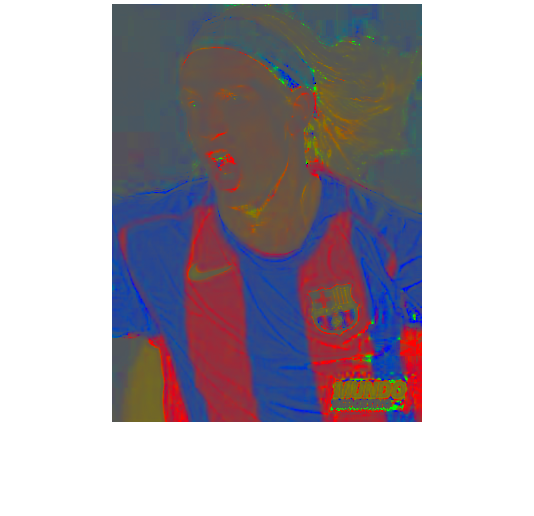

imageModel = imagePreProcessing(imread('./soccer/barcelona/05.jpg'));
plotHistogramAndImage(imageModel);

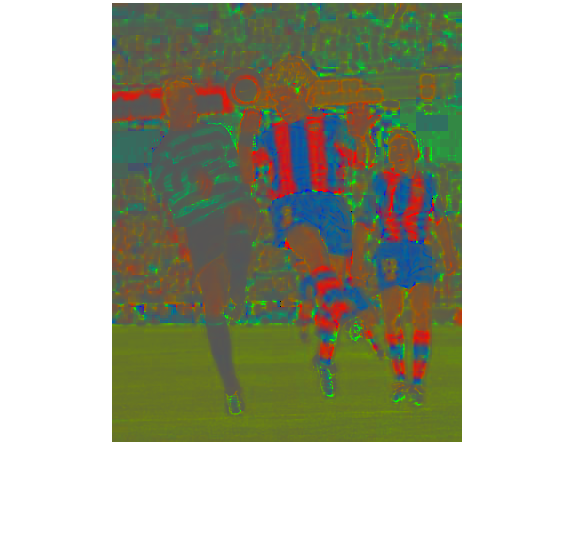


imageModel = imagePreProcessing(imread('./soccer/barcelona/10.jpg'));
plotHistogramAndImage(imageModel)

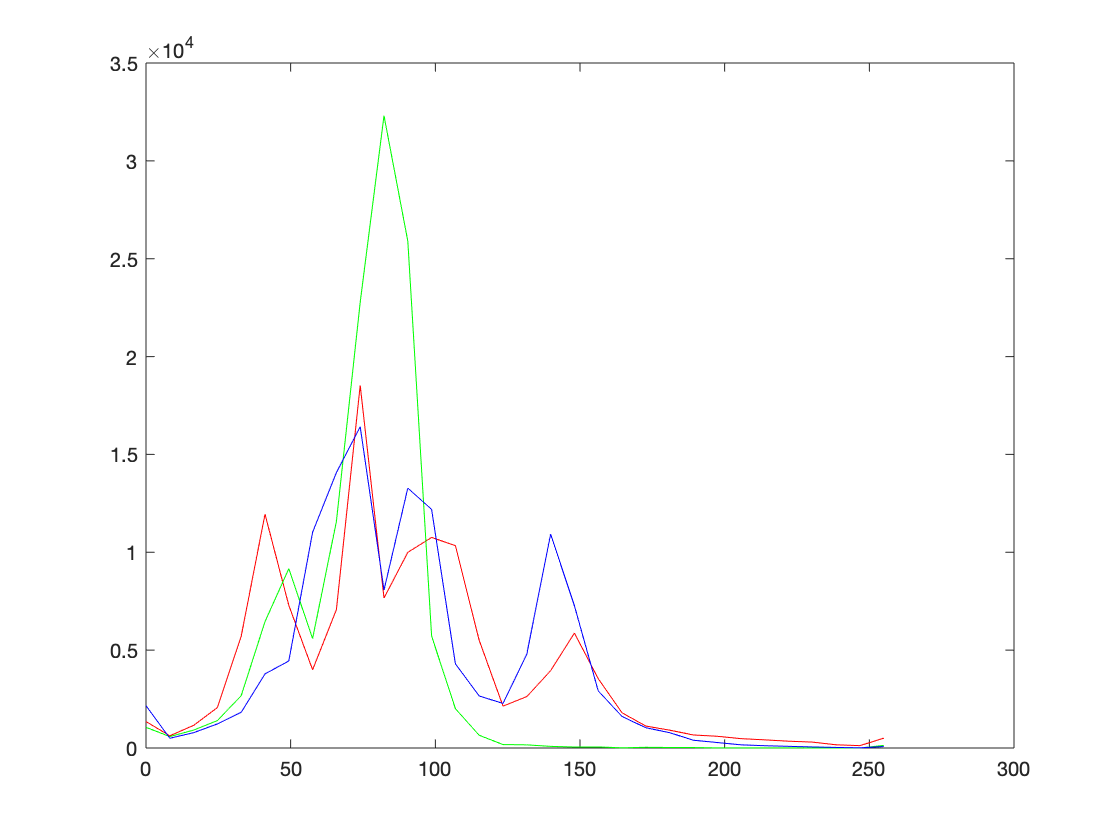

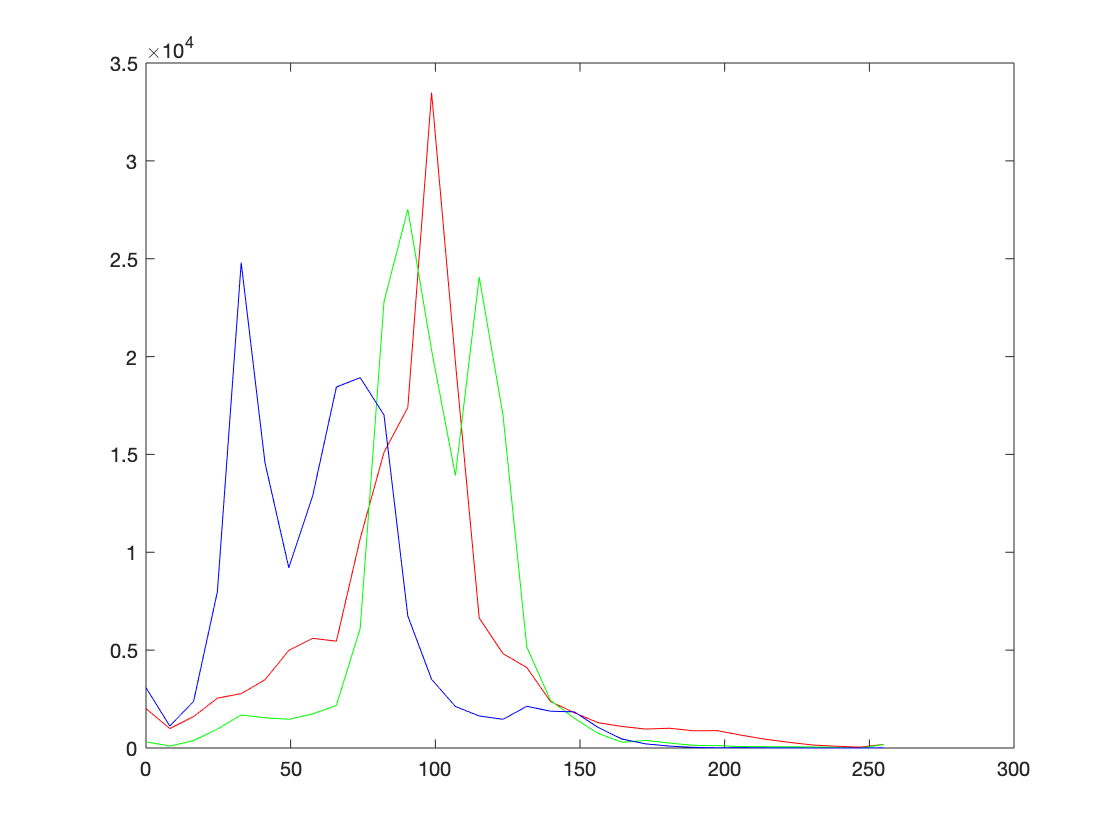

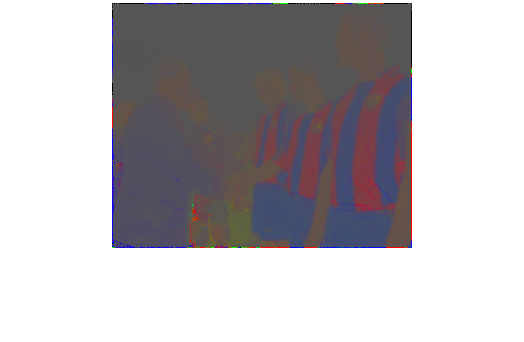

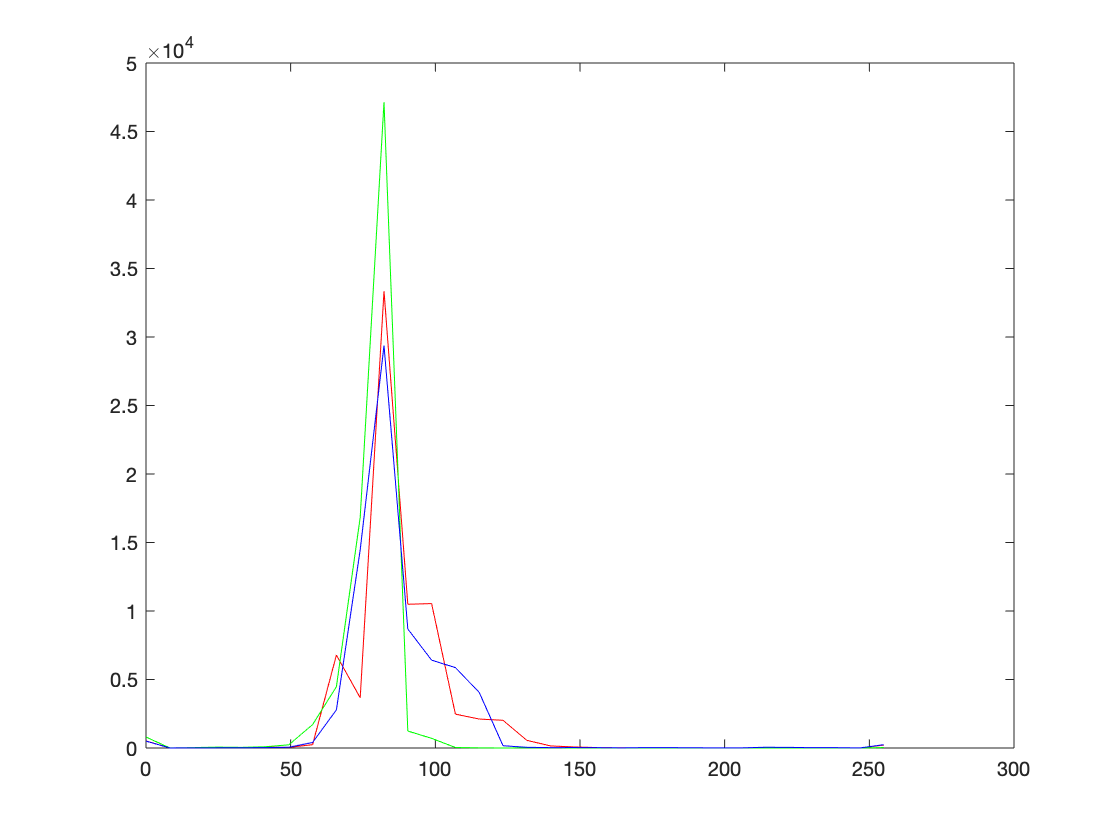


imageModel = imagePreProcessing(imread('./soccer/barcelona/12.jpg'));
plotHistogramAndImage(imageModel)

## Functions

    Image preprocessing function:

function impp = imagePreProcessing(im)
    % Image components extraction
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    % Color normalization
    I = double(r) + double(g) + double(b);
    Rn = double(r) ./ I;
    Gn = double(g) ./ I;
    Bn = double(b) ./ I;
    
    impp = uint8(cat(3, Rn, Gn, Bn) * 255);
end

    Function to perform the Model-Image Comparison:

function result = compareModelImage(modelH, im)
    % Input image preprocessing
    imPreprocessed = imagePreProcessing(im);
    
    % Input image (preprocessed) histogram
    imH = imhist(imPreprocessed);
    
    % Compare histograms
    
end

function v = plotHistogramAndImage(im)
    figure;
    imshow(im);
    h = imhist(im);

    R = im(:,:,1);
    G = im(:,:,2);
    B = im(:,:,3);
    
    [yRed x] = imhist(R, 32);
    [yGreen x] = imhist(G, 32);
    [yBlue x] = imhist(B, 32);
    
    figure;
    plot(x, yRed, 'R', x, yGreen, 'G', x, yBlue, 'B');
    
end